# Frequency calculation

There are two ? marks in the calculation 

## Fw=sum(?.*exp(-j*?*t_vector))*t_step;

Change them to correct code and run the section.

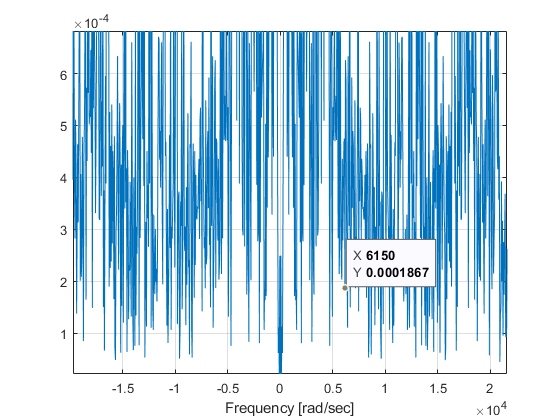


clear   %Remove items from workspace, freeing up system memory
load sampled_ft.mat %Load sample_ft.mat from file into workspace
t_step= t_vector(2) - t_vector(1);

Fw_vector=[];
w_vector=[];
for w=-25000:50:25000
    
  
    Fw=sum(ft_vector.*exp(-j*w*t_vector))*t_step;
    w_vector=[w_vector w];
    Fw_vector=[Fw_vector Fw];
    
end
plot(w_vector,abs(Fw_vector))
xlabel('Frequency [rad/sec]')
grid

xlim([-19743 21579])
ylim([0.000021 0.000682])